# 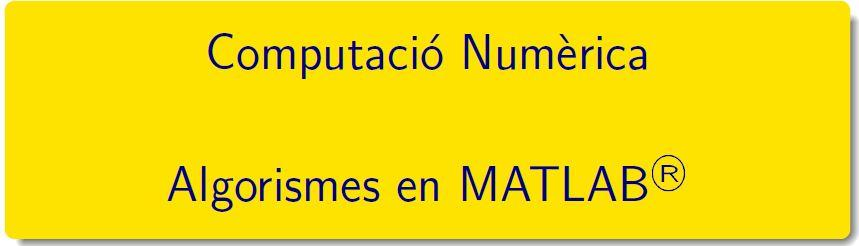

====================================================================================

# Pràctica 2 - Activitat 2: evitar propagació errors

`Document preparat per M. Àngela Grau Gotés, 22 de febrer de 2023`

## Algorismes

### Evitar la propagació d'errors

Per tal de reduir o evitar la propagació dels errors es recomana, minimitzar el nombre d’operacions, reordenar les operacions i replantejar el problema en altres termes.

#### Exercici 10, pàgina 21. Equació de segon grau

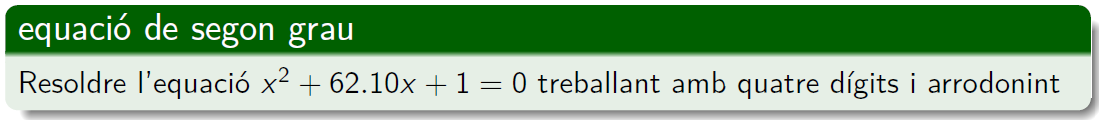

clearvars, format longG
n=4;
fprintf('fent ús de roots'), arrels =roots([1,62.10 1])%calcula les arrels del polinomi

fent ús de roots

arrels =           -62.083892762591
       -0.0161072374089686


Es calcula amb la fórmula $\frac{-b\pm\sqrt{b^2-4ac}}{2a}=-31.05\pm\sqrt{31.05^2-1}$

aux1=round((31.05)^2,n,'significant') 

aux1 =                      964.1


Es calcula amb la fórmula $x_1=-31.05-\sqrt{31.05^2-1},\quad  x_3 = 1/x_1$

aux2=round(sqrt(aux1-1),n,'significant'), sqrt(31.05^2-1)

aux2 =                      31.03


ans =            31.033892762591


Xifres decimales correctes

x1 = round(-31.05-aux2,n,'significant')

x1 =                     -62.08


x2 = round(-31.05+aux2,n,'significant')

x2 =                      -0.02


x3 = round(1/x1,n,'significant')

x3 =                   -0.01611


#### Exercici 11, pàgina 21. Equació de segon grau Regla de Horner

Per avaluar expressions polinomials 

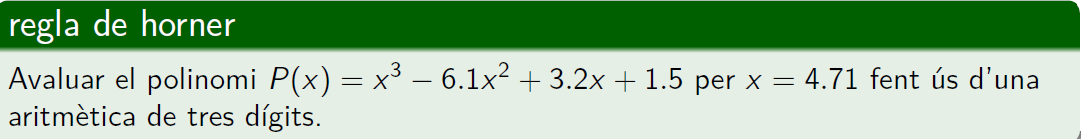

- Evaluar el polinomi $x^3 -6\ldotp 1x^2 +3\ldotp 2x+1\ldotp 5$ en $x=4\ldotp 71$

clearvars   %, format shortG
x=4.71, n=3; 

x =                       4.71


coeffs = [1,-6.1,3.2,1.5];
valor_exacte = horner(coeffs,x)

valor_exacte =                 -14.263899


valor_horner_digits = hornerD(coeffs,4.71,n)

pa =      0


valor_horner_digits =      0


xs = abs((valor_horner_digits-valor_exacte)/valor_exacte);

- Evaluar el polinomi $x^3 -6\ldotp 1x^2 +3\ldotp 2x+1\ldotp 5$ en $x=4\ldotp 71$fent ús d'una aritmètica aritmética de tres dígits

Suma ordre creixent potències x

Suma ordre decreixent potències x

- Error relatiu

function [ pa ] = horner(coeff,a)
%   HORNER avalua el polinomi de grau n
%   p(x) = coeff(1)x.^n + coeff(2)x.^(n-1) + ... + coeff(n-1)x + coeff(n)
%   en x=a pel mètode de horner
pa = coeff(1);
x=a;
for k=2:length(coeff)
    pa = pa.*x + coeff(k);
end
return
end
function [ pa ] = hornerD(coeff,a,d)
%   HORNER avalua el polinomi de grau n
%   p(x) = coeff(1)x.^n + coeff(2)x.^(n-1) + ... + coeff(n-1)x + coeff(n)
%   en x=a pel mètode de horner fent ús de d dígits
pa = 0;
return
end

`Document preparat per M. Àngela Grau Gotés, 22 de febrer de 2023`